Global Orbital Launch Defense

Shane Dirks and Nick Folz

AA279B Final Project

Spring of 2018

clear all;

fileID = fopen('vehicleinfo.txt','r');

x = textscan(fileID,'%s',1,'delimiter','\n\r');
header1 = cell2mat(x{1});
y = textscan(fileID,'%s',1,'delimiter','\n\r');
header2 = cell2mat(y{1});

data = cell2mat(textscan(fileID,'%f %f %f %f %f %f %f',3,'delimiter','/n/r'));
fclose('all');
clearvars fileID x y

vehicles = data(end,1);
R_vehicles_ECI = data(:,2:4);
V_vehicles_ECI = data(:,5:7);

days = 6574.5; %solar days between jan 1, 2000 12:00 until jan1 2018, 00:00
%per wolfram alpha
theta_epoch = mod((280.4606 + 360.9856473*days)/180*pi,2*pi); %in radians


% Define constants and stuff
R_earth = 6378.1;
omega_earth = 0.0000729211585530;%rad/sec per HW3
mu_earth = 398600.4418;
time_sim = 45.4*86400; %number of sec (days*86400) since epoch
tlength = 1*3600; %hours of simulation

tvec = time_sim:1:time_sim+tlength;
thetavec = mod((280.4606 + 360.9856473*tvec/86400)/180*pi,2*pi);
size_for_things = 100;

%target things
target_alt = 1200;
target_ratio = (R_earth+target_alt)/R_earth;

% Plot Initial Vehicle positions
if(0) 
    
figure
earth_sphere(size_for_things);
hold on
for i = 1:vehicles
[r,v] = ECI2ECEF(R_vehicles_ECI(i,:),V_vehicles_ECI(i,:),thetavec(1),omega_earth);
plot3(r(1),r(2),r(3),'or','MarkerFaceColor','r')
end
title('Initial Vehicle Positions')

end

if 0
close all
figure
earth_sphere(size_for_things);

lim = caxis;
hold on
colorbar
[a,b,c] = sphere(size_for_things/2);

if 1
a = a*R_earth*1.2+0*R_earth;
A = a;
A(A<0) = NaN;

b = b*R_earth*1.2+0*R_earth;
B = b;
B(B<0) = NaN;
c = c*R_earth*1.2+0*R_earth;
C = c;
C(C>4/8*max(C)) = NaN;
end
%y = (y>0)*R_earth*1.2; z = (z>0)*R_earth*1.2;
surf(A,B,C,a.*0-7000,'FaceAlpha',.5)
%caxis = lim;
%earth_sphere(size_for_things);
max(max(c));
max(max(C));
caxis = lim;
hold off
end


r1 = R_vehicles_ECI(1,:)';
v1 = V_vehicles_ECI(1,:)';
options = odeset('RelTol', 1e-6, 'AbsTol', 1e-9);
%earth to jup section
tvec = 0:.01:60*5;
odefun = @(tout,yout) differinertial(tout,yout,mu_earth);
[tout,yout] = ode113(odefun,tvec,[r1;v1],options);


% finding sat 1 intercept possibilities



%define search_space
theta = linspace(0,2*pi,size_for_things);
phi = linspace(0,pi,size_for_things);
r = target_ratio*R_earth;

[x,y,z] = sphere(size_for_things);
x = x*r;
y = y*r;
z = z*r;
v1_out = x.*NaN;
success = v1_out;
for i = 1:length(x)
    for j = 1:length(y)
        [vout, ~] = lambert_v(mu_earth,r1,[x(i,j) y(i,j) z(i,j)],'s',0,25*60);
        success(i,j) = norm(v1-vout);
        [v2out,~] = lambert_v(mu_earth,yout(end,1:3),[x(i,j) y(i,j) z(i,j)],'s',0,20*60);
        success2 = norm(yout(end,4:6)-v2out);
        if success(i,j)>success2
            success(i,j) = success2;
        end
        
        v1_out(i,j,1:3) = vout;
    end
end

impos180 


tits = success;
tits(success>4) = NaN;



[xearth,yearth,zearth] = earth_sphere(size_for_things);
h(1) = surf(xearth,yearth,zearth);

cvalue1 =    1.0e+03 *

   -6.3781    6.3781


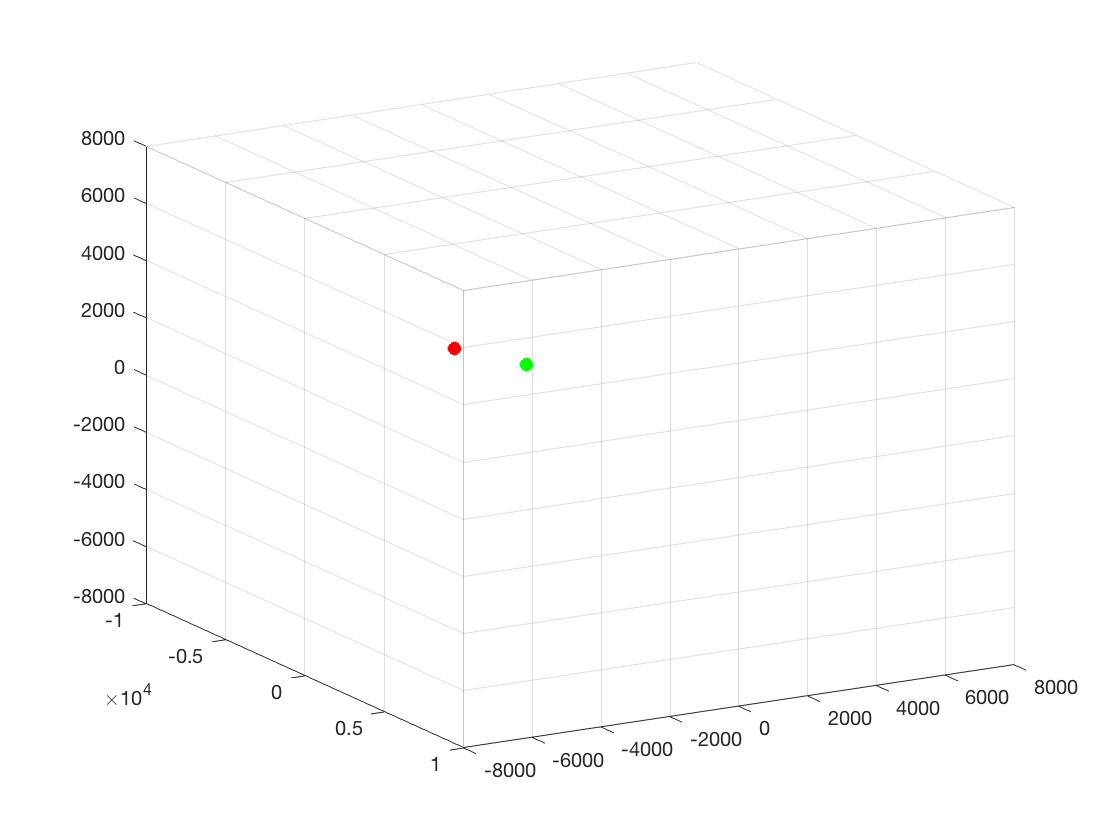

hold on
h(2) = surf(x,y,z,tits,'FaceAlpha',.7);




load('topo.mat','topo','topomap1');

a = colormap([topomap1;autumn(64)]);

cmapsize = 64;  % 64-elements is each colormap
cvalue1 = [-7473 ,5731];
cvalue2 = [0,max(tits)];
% CData for surface

C1 = min(cmapsize,round((cmapsize-1)*(topo-cvalue1(1))/(cvalue1(2)-cvalue1(1)))+1); 
% CData for pcolor
C2 = 64+min(cmapsize,round((cmapsize-1)*(topo-cvalue1(1))/(cvalue1(2)-cvalue1(1)))+1);
% Update the CDatas for each object.
set(h(1),'CData',C1);
set(h(2),'CData',C2);
% Change the CLim property of axes so that it spans the 
% CDatas of both objects.
caxis([min(C1(:)) max(C2(:))])









h(3) = plot3(r1(1),r1(2),r1(3),'or','MarkerFaceColor','r');
h(4) = plot3(yout(end,1),yout(end,2),yout(end,3),'og','MarkerFaceColor','g');

grid on
view([30 -20])



hold off